addpath("toolbox")

mutations = 96

mutations = 96

k = 5;  % Number of components in the dictionary
%https://doi.org/10.1093/bioinformatics/btw572
dir = 'C:\Files\github\Mutational_Signatures\'

dir = 'C:\Files\github\Mutational_Signatures\'

files = ["simulated_data/experiment_noise_1/data_v1_GRCh37_4_6_7a_9_18.csv", "simulated_data/experiment_noise_1/data_v2_GRCh37_4_6_7a_9_18.csv", "simulated_data/experiment_noise_1/data_v3_GRCh37_4_6_7a_9_18.csv", "simulated_data/experiment_noise_1/data_v4_GRCh37_4_6_7a_9_18.csv", "simulated_data/experiment_noise_1/data_v5_GRCh37_4_6_7a_9_18.csv", "simulated_data/experiment_noise_1/data_v6_GRCh37_4_6_7a_9_18.csv", "simulated_data/experiment_noise_1/data_v7_GRCh37_4_6_7a_9_18.csv"]

files = 1×7 string array
    "simulated_data/experiment_noise_1/data_v1_GRCh37_4_6_7a_9_18.csv"    "simulated_data/experiment_noise_1/data_v2_GRCh37_4_6_7a_9_18.csv"    "simulated_data/experiment_noise_1/data_v3_GRCh37_4_6_7a_9_18.csv"    "simulated_data/experiment_noise_1/data_v4_GRCh37_4_6_7a_9_18.csv"    "simulated_data/experiment_noise_1/data_v5_GRCh37_4_6_7a_9_18.csv"    "simulated_data/experiment_noise_1/data_v6_GRCh37_4_6_7a_9_18.csv"    "simulated_data/experiment_noise_1/data_v7_GRCh37_4_6_7a_9_18.csv"


disp(files(1))

simulated_data/experiment_noise_1/data_v1_GRCh37_4_6_7a_9_18.csv


data_table = readtable(strcat(dir, files(1)), ReadRowNames=true, ReadVariableNames=true);



disp(data_table)

                x0     x1      x2     x3     x4      x5     x6      x7      x8     x9     x10    x11    x12    x13    x14     x15     x16     x17     x18     x19    x20     x21    x22     x23    x24    x25     x26     x27    x28     x29    x30    x31    x32    x33     x34    x35    x36     x37    x38     x39    

data = table2array(data_table)

data =          442          12          53         284         321        1474          97         513         458          14         211          25         133         509         451        1335          41          64         293          79        2359         216        1245          92          49         402         647         214         997          51         110         114          40         765          40          32        1442          89         305         216          66         163          87          14         473         378          52        2100        1034         136
         515          18          64         187         268        1004         120         328         470          25         139          17          95         313         363         760          58          52         252          40         990         173         653          34          52         297         393         207         811          88          74         113        

% Normalize each column to sum to 1
data = bsxfun(@rdivide, data, sum(data));

## Generate Cost Matrix M

x = linspace(0, 1, mutations);  % Adjust to the appropriate number of rows
M = abs(bsxfun(@minus, x', x));
M = M / median(M(:));  % Normalize M by its median

## Parameters for Wasserstein Dictionary Learning

options.stop = 1e-3;
options.verbose = 2;
options.D_step_stop = 5e-5;
options.lambda_step_stop = 5e-4;
options.alpha = 0.5;
options.Kmultiplication = 'symmetric';
options.GPU = 0;


% Create legend labels
dictionaryLegendArray = cell(1, k);
for i = 1:k
    dictionaryLegendArray{i} = ['$d_{', num2str(i), '}$'];
end

gamma = 1 / 50;
wassersteinOrder = 1;
rho1 = 0.1;
rho2 = 0.1;

% Ensure dimensions of data and M are compatible
disp(['Size of data: ', mat2str(size(data))]);

Size of data: [96 50]


disp(['Size of M: ', mat2str(size(M))]);

Size of M: [96 96]


## Perform Wasserstein Dictionary Learning

Ensure data size matches what wasserstein_DL expects

[D, lambda, objectives] = wasserstein_DL(data, k, M .^ wassersteinOrder, gamma, rho1, rho2, options);

Optimize with respect to lambda
	Dual iteration : 0 Objective : 12.679118, Current step size 1.000000
		Gradnorm=0.654033 stop=0.000500
	Dual iteration : 1 Objective : 12.416781, Current step size 1.000000
		Gradnorm=0.555286 tol=0.000750
	Dual iteration : 21 Objective : 9.090125, Current step size 0.187575
		Gradnorm=0.167467 tol=0.008573
	Dual iteration : 41 Objective : 7.595181, Current step size 0.234469
		Gradnorm=0.104394 tol=0.016912
	Dual iteration : 61 Objective : 7.211898, Current step size 0.120048
		Gradnorm=0.040457 tol=0.021236
	Dual iteration : 1 Objective : 7.164043, Current step size 0.054976
		Gradnorm=0.023246 tol=0.022031
	Dual iteration : 2 Objective : 7.162950, Current step size 0.068719
		Gradnorm=0.019457 stop=0.022033
Optimize with respect to D
	Dual iteration : 0 Objective : 6.914103, Current step size 1.000000
		Gradnorm=0.619325 stop=0.000050
	Dual iteration : 1 Objective : 6.786759, Current step size 0.512000
		Gradnorm=0.461450 tol=0.000063
	Dual iteration

## Visualization Parameters

minY = 0;
maxY = 0.1;
YtickStep = 0.02;
indices = 1:3;  % Change as needed based on your data
fontSize = 30;
lineWidth = 4;
axisValues = [0, 1, minY, maxY];  % Adjust to fit your data range

% Legend for data samples
dataLegendArray = cell(numel(indices), 1);
for i = 1:numel(indices)
    dataLegendArray{i} = ['$x_{', num2str(i), '}$'];
end

## Visualize Data

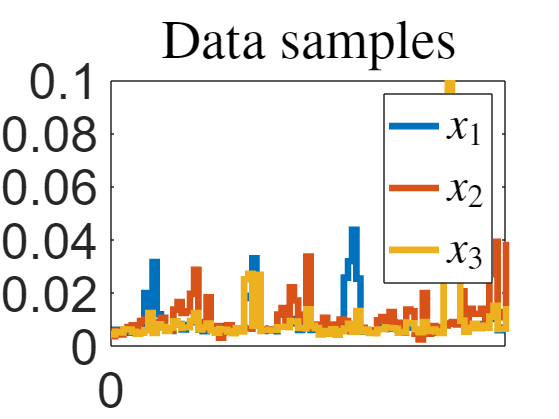

plotDictionary(x, data(:, indices), axisValues, lineWidth, fontSize, YtickStep, 0, dataLegendArray, 'Data samples');

## Compare Data and Reconstruction

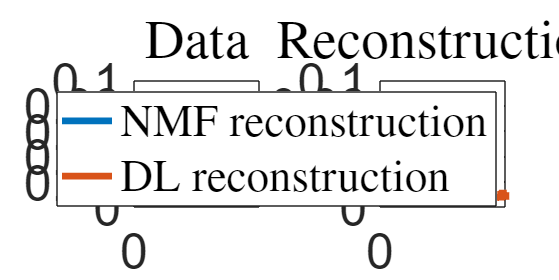

width = 1200;
height = 600;
figure('Position', [1, 1, width, height]);

% Adjust axis values for comparison
axisValues(3) = 0;
minY = 0;
i = 1;  % Index of the data sample to compare

subplot(1, 2, 1);
plotDictionary(x, data(:, i), axisValues, lineWidth, fontSize, YtickStep, 0, 'x', 'Data');

subplot(1, 2, 2);
plotDictionary(x, [D * lambda(:, i), D * lambda(:, i)], axisValues, lineWidth, fontSize, YtickStep, 0, {'NMF reconstruction', 'DL reconstruction'}, 'Reconstruction');

## Visualize Learned Matrices D and Lambda

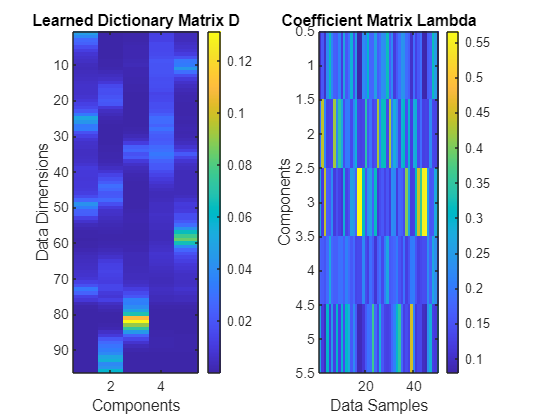

% Visualize the learned dictionary D as a heatmap
figure;
subplot(1, 2, 1);
imagesc(D);  % Display matrix D as an image
colormap(parula);
colorbar;
title('Learned Dictionary Matrix D');
xlabel('Components');
ylabel('Data Dimensions');

% Visualize the coefficient matrix Lambda as a heatmap
subplot(1, 2, 2);
imagesc(lambda);  % Display matrix lambda as an image
colormap(parula);
colorbar;
title('Coefficient Matrix Lambda');
xlabel('Data Samples');
ylabel('Components');

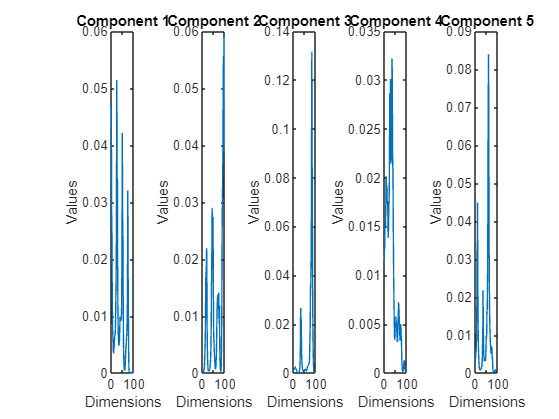


% Optionally, you can also display individual components of D if needed:
figure;
for i = 1:size(D, 2)
    subplot(1, size(D, 2), i);
    plot(D(:, i));
    title(['Component ', num2str(i)]);
    xlabel('Dimensions');
    ylabel('Values');
end